# CMSE 821: Numerical Differential Equations / Final Exam

Student: Jorge A. Martinez Ortiz

Date Due: 12.14.2023

## Tasks

Instantiate the Crystal-growth class that encapsulates the dynamics of dendritic crystal growth

% Define stencils
stencil_phi = [0  1  0;
               1 -4  1;
               0  1  0];

stencil_T   = [0  1  0;
               1 -4  1;
               0  1  0];

% Define parameters
params = struct('M',3000,...
                'alpha',0.9,...
                'gamma',10,...
                'Tm',1,...
                'K',1.6,...
                'h',0.03,...
                'xlim',[0 9],...
                'ylim',[0 9],...
                'epsilon',0.01,...
                'stencil_phi',stencil_phi,...
                'stencil_T',stencil_T);

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y))

cg =   Crystal_growth with properties:

                        M: 3000
                    alpha: 0.9000
                  epsilon: 0.0100
                    gamma: 10
                       Tm: 1
                        K: 1.6000
                        x: [301×301 double]
                        y: [301×301 double]
                        h: 0.0300
                       sz: [301 301]
    phi_initial_condition: @(x,y)phi_initial_condition(x,y)
      T_initial_condition: @(x,y)T_initial_condition(x,y)
              stencil_phi: [3×3 double]
                stencil_T: [3×3 double]
           stencil_grad_x: [3×3 double]
           stencil_grad_y: [3×3 double]
                        p: [1×1×89401 double]
                   phi_bc: @(phi)Crystal_growth.boundary_conditions(phi)
                     T_bc: @(T,x)Crystal_growth.boundary_conditions(T)
                 T_naught: [301×301 double]
               phi_naught

### Task 1


$$\phi_0 = \frac{1}{2}\Big[1-\tanh \Big(\frac{r-0.25}{0.015}\Big)\Big] \eta$$


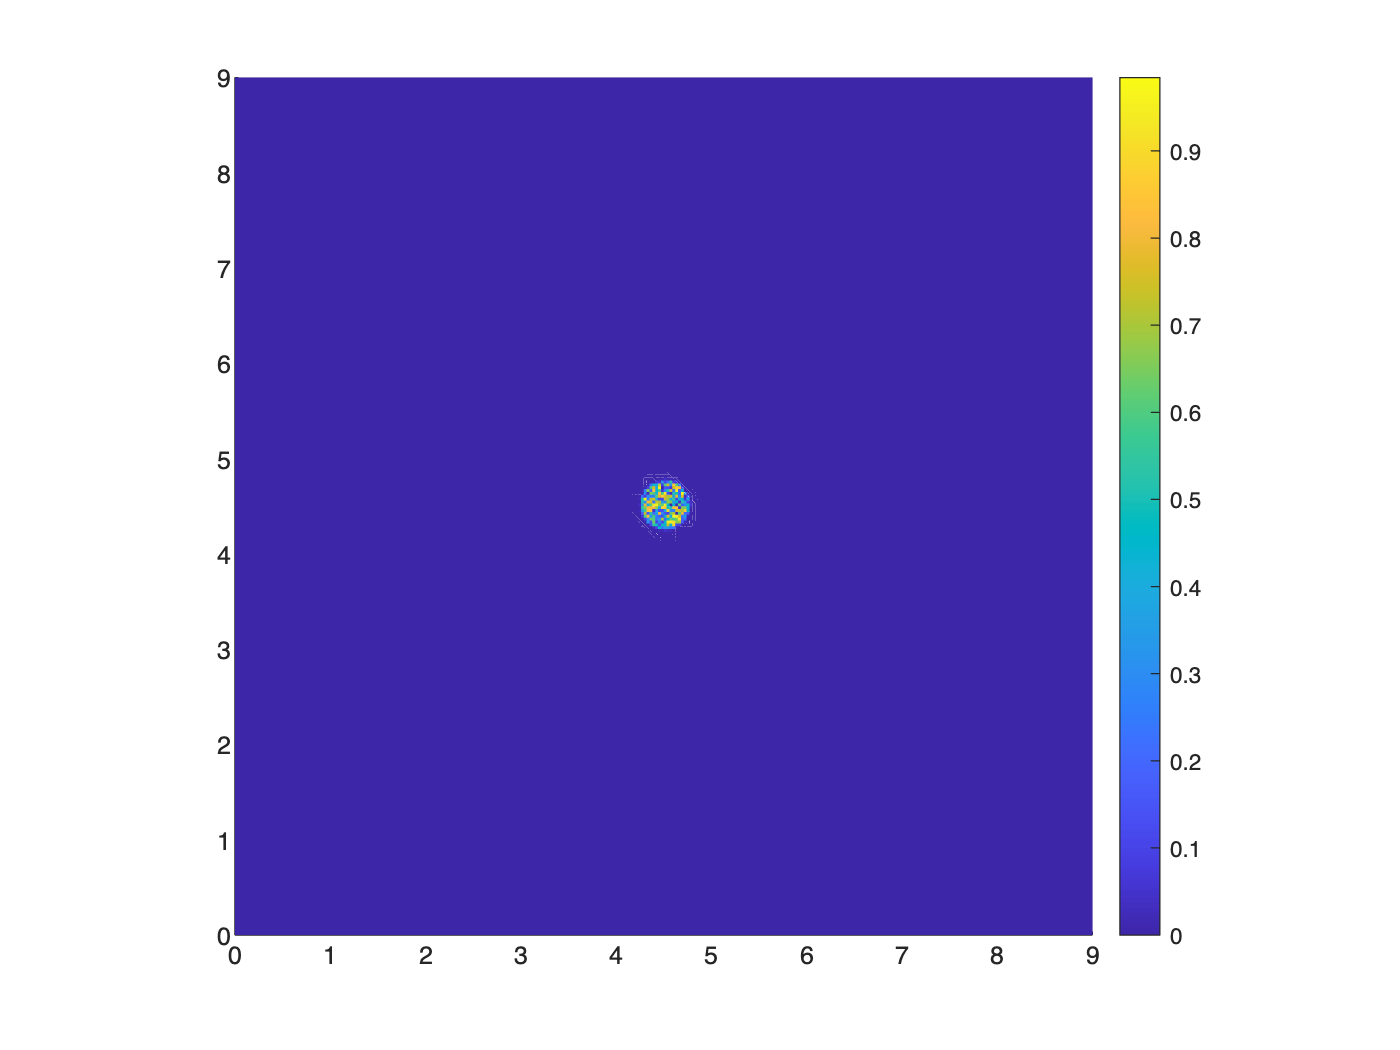

figure
fdraw(cg.x,cg.y,cg.phi_naught)

### Task 2

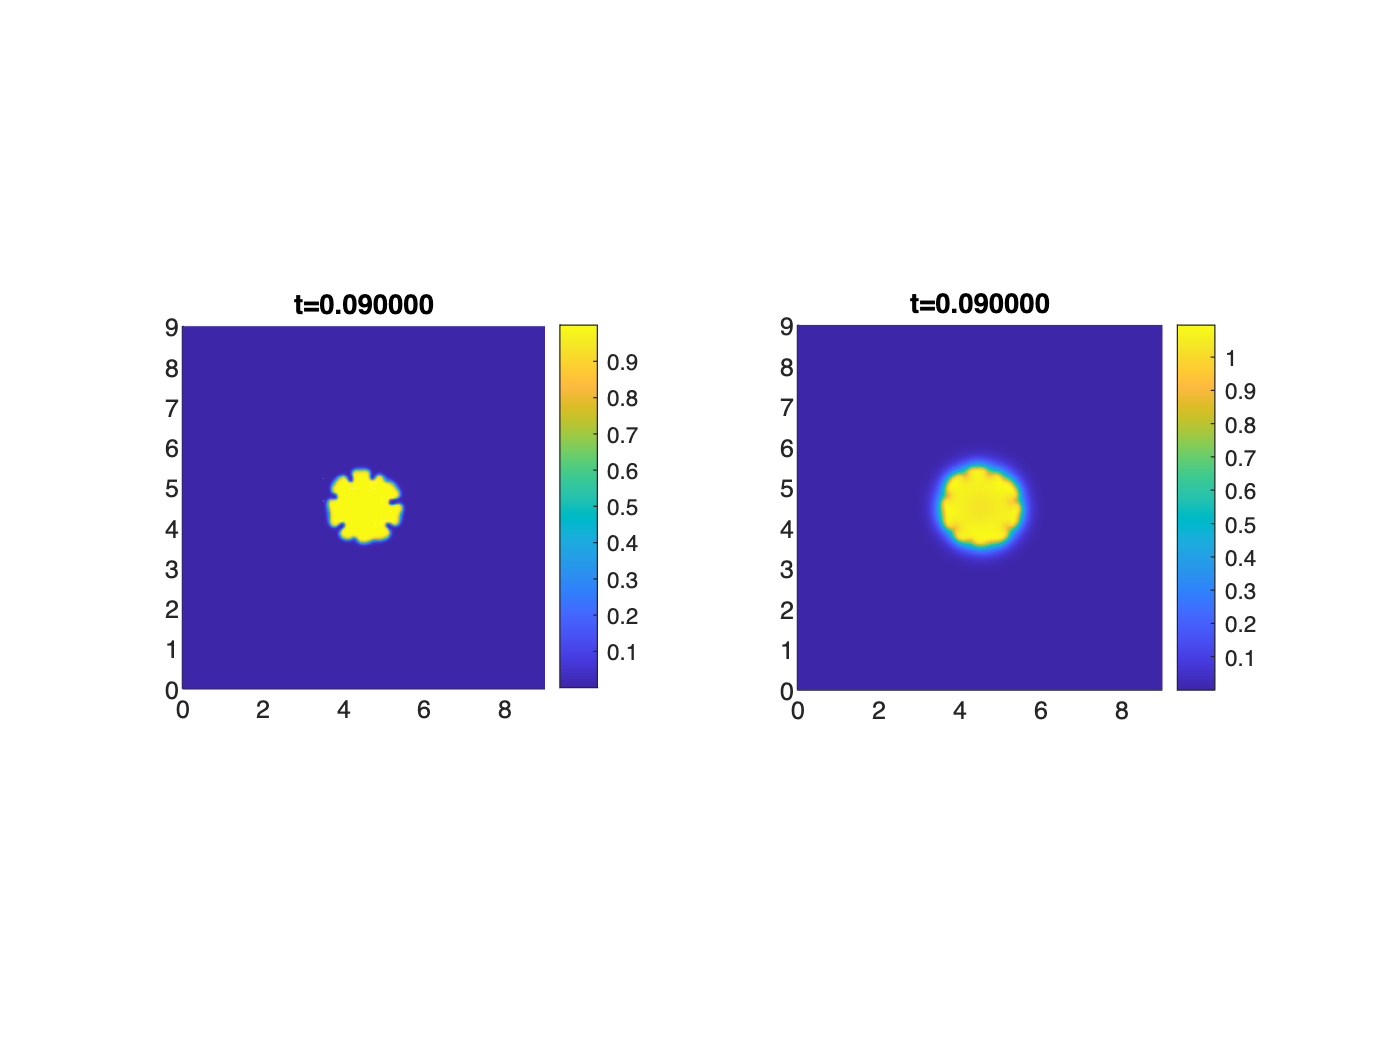

t_span = [0 0.45];
k = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 3

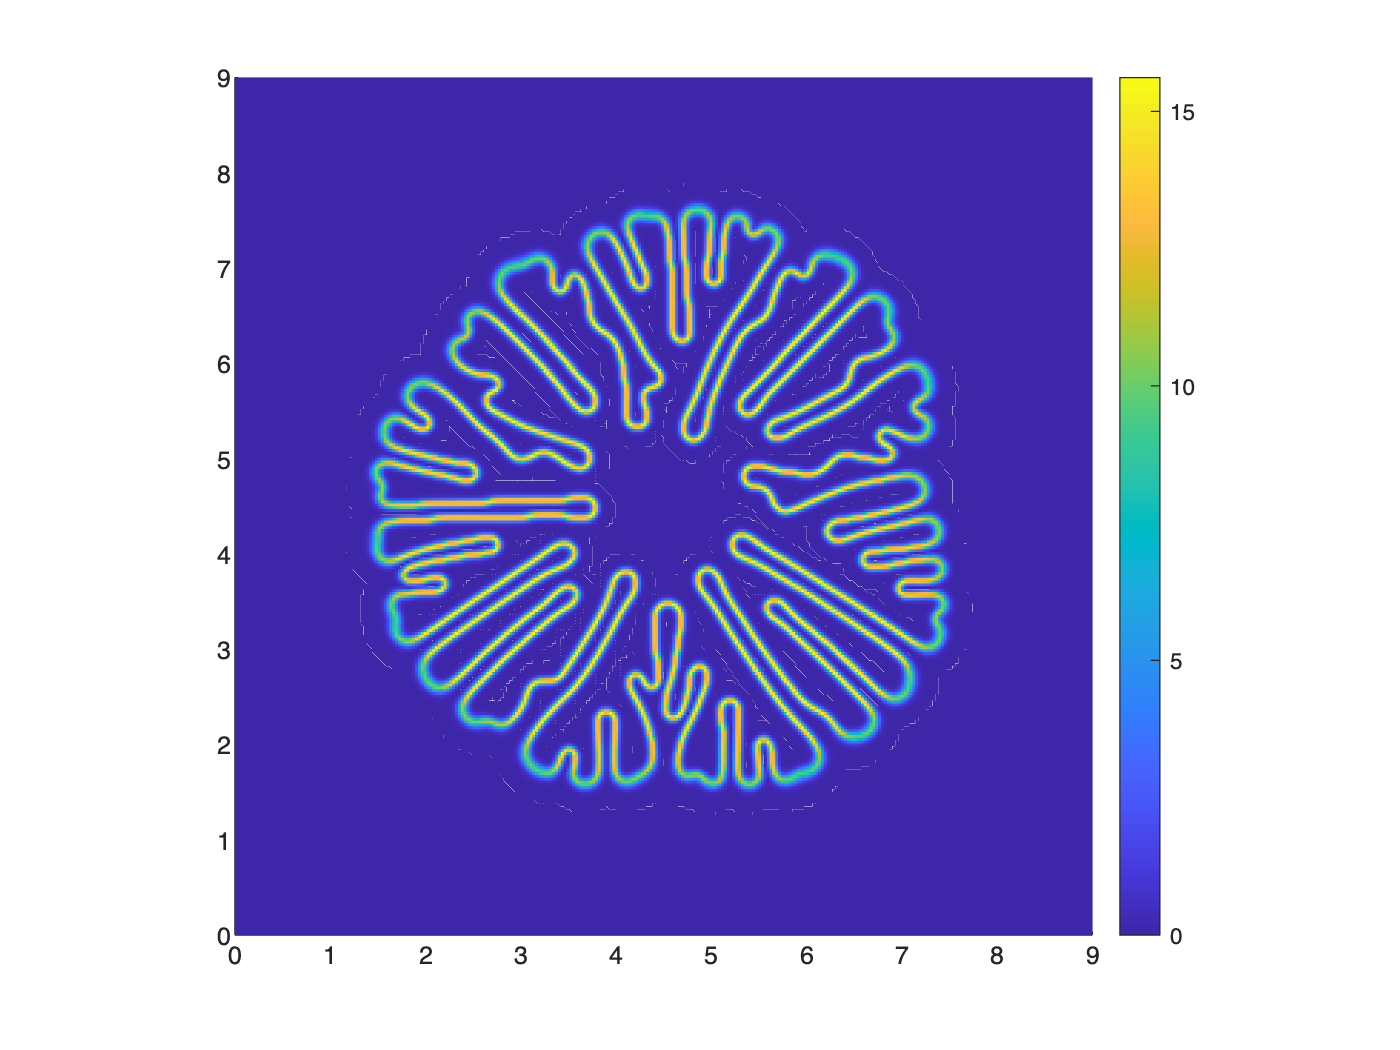

% Calculate gradient
[fx,fy,mag,idx] = cg.grad(phi);

% Select points
mag(~idx) = 0;

% Draw magnitude of the gradient
figure
fdraw(cg.x,cg.y,mag);

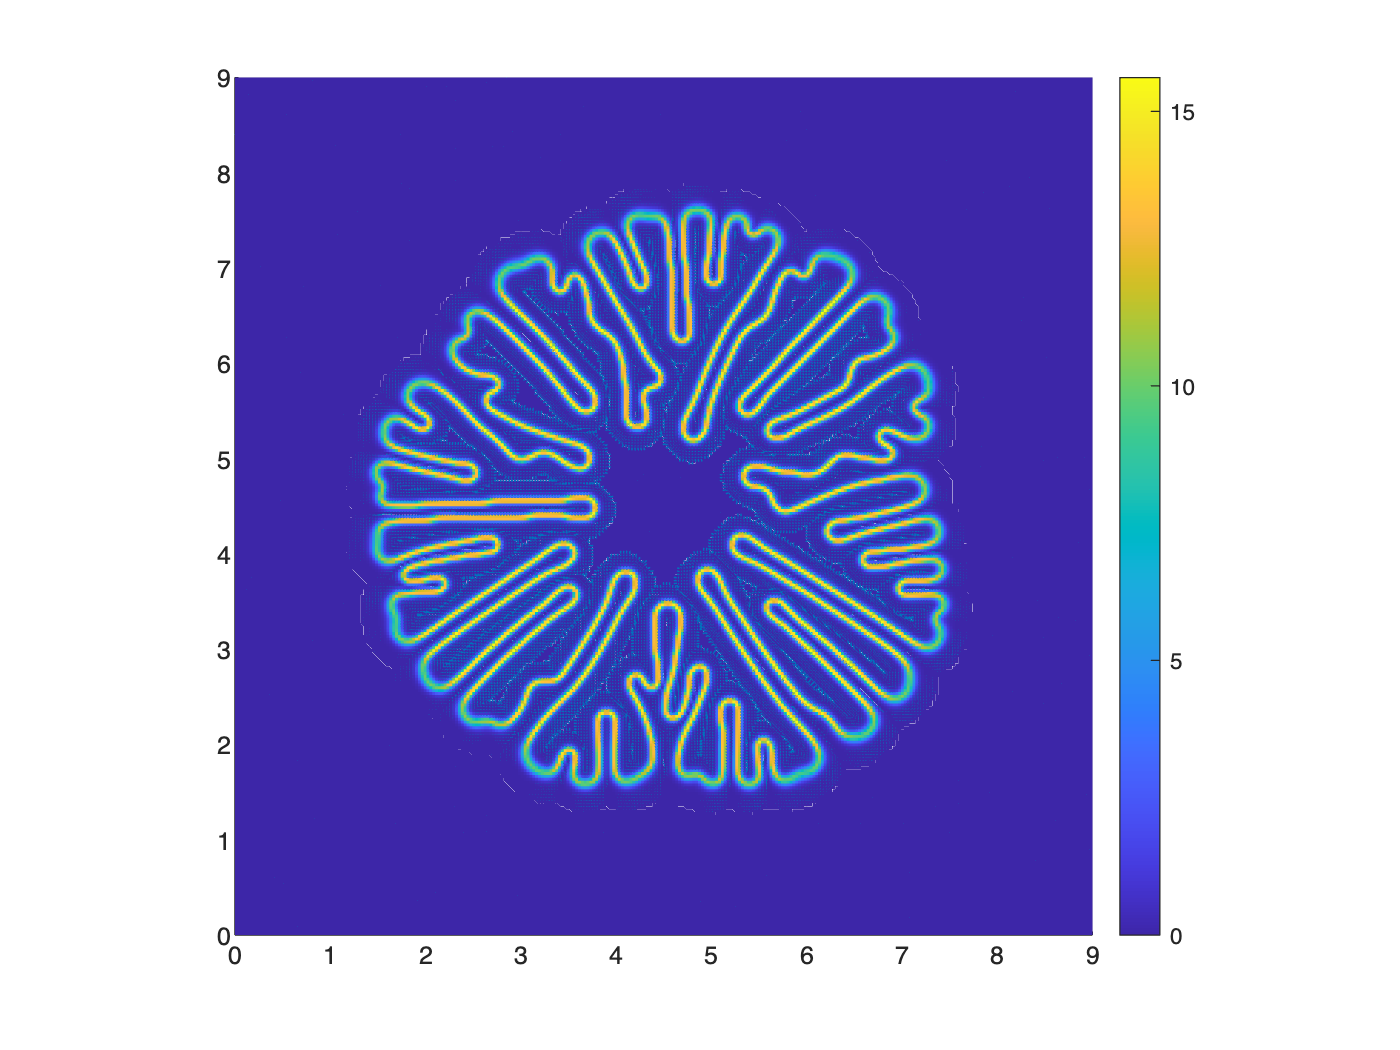

% Draw inward pointing vector
[theta,nx,ny] = cg.inward_vector(phi);

figure
fdraw(cg.x,cg.y,mag)
hold on
quiver(cg.x,cg.y,nx,ny)

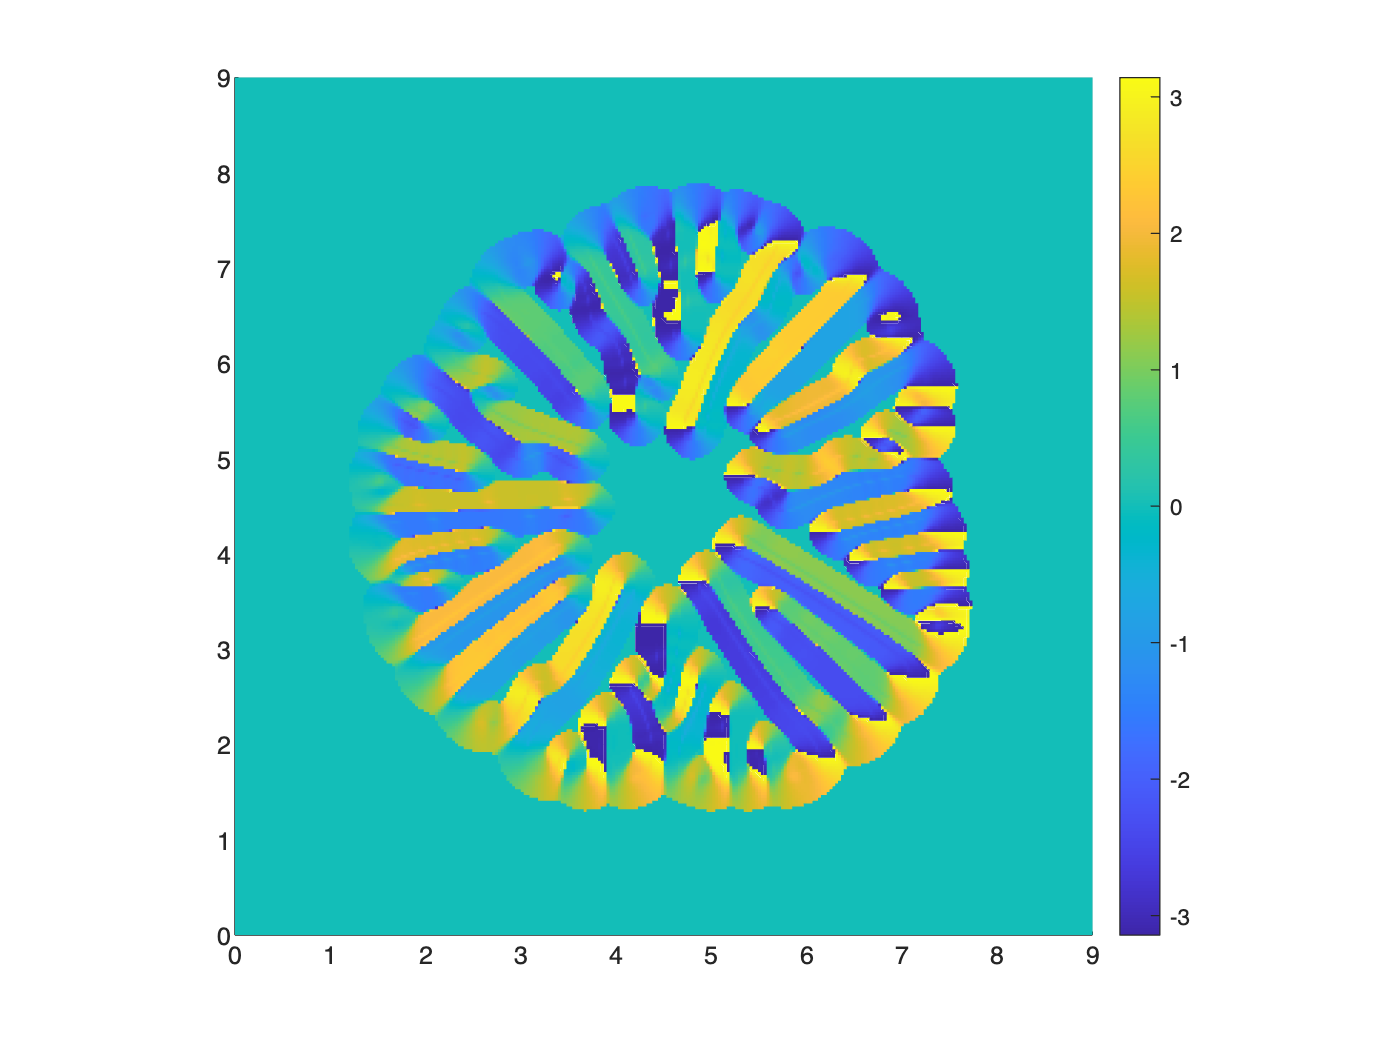

figure
fdraw(cg.x,cg.y,theta)

### Task 4

### Task 5

### Task 6

## Functions

function phi_naught = phi_initial_condition(x,y)
    %INITIAL_CONDITION Generates the initial condition to the
    %problem given the discretizations along the x and y 
    % directions
    theta = (hypot(x-4.5,y-4.5)-0.25)/0.015;
    phi_naught = 1/2 * (1 - tanh(theta)) .* rand(size(theta));
end

function T_naught = T_initial_condition(x,y)
    T_naught = zeros(size(x));
end

function U = f_bc1(U)
    U(1,2:end-1) = U(2,2:end-1);          % North row
    U(end,2:end-1) = U(end-1,2:end-1);    % South row 
    U(1:end,1) = U(1:end,2);              % West row
    U(1:end,end) = U(1:end,end-1);        % East row
end
